# **Popularity Plotting**

Now that we've looked at the different ways MATLAB allows us to communicate data in the form of various plots and walked through creating a plot by importing data into MATLAB, you're going to try it on your own! See if you can make a plot using a different popularity index from the LilPump data file.

Run the cell below to see the plot from the previous notebook detailing Lil Pump's popularity:

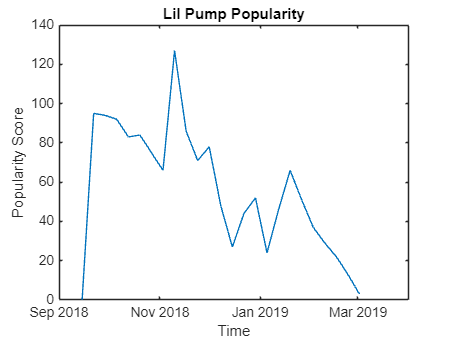

%this will clear the workspace and import the Lil Pump Data
clc;clear;
data = readcell("/MATLAB Drive/MATLAB - Section 04 (Student - File Share)/Data/lilpumpdata.xlsx");

%this will grab the popularity rank and the dates from the data file that
%we imported
rank = data(2:end,5); 
date = data(2:end,3);

%combine rank and date into a 2D array
cell_array = [date, rank];
%convert from type 'cell' to type 'table'
data_table = cell2table(cell_array,'VariableNames',{'Date','Rank'});
%convert to timetable
music_timetable = table2timetable(data_table);

%access Date and Rank colums and select items 78 through 102 
% (as this is where we would like to zoom)
plot(music_timetable.Date(78:102), music_timetable.Rank(78:102)); 
%lets add a title for clarity
title("Lil Pump Popularity");
%label axes
xlabel("Time");
ylabel("Popularity Score");

**Exercise:**

Now see if you can make a plot using a different popularity index from the LilPump data file, how does your chart compare with the original?

You can also plot other features such as danceability, try double clicking the "data" variable in your workspace to look at the different features in each column!

%%YOUR CODE GOES HERE%%



 